# Cessna 620

clear;
clc;

## Variables

% Longitudinal
g = 32.2;                % ft/s^2
Xu = -.0374;             % 1/s
Xalpha = 17.4632;        % ft/s^2
Xq = 0;
Theta1long = 6 *pi/180;  % rad
Xtheta = -g*cos(Theta1long);
Zu = -.3404 ;            % 1/s
Zalpha = -170.4133;      % ft/s^2
Zq = -4.0997;            % ft/s
Ztheta = -g*sin(Theta1long);
Mu = 0;             % 1/ft/s
Malpha = -5.5002;        % 1/s^2
Mq = -2.1809;             % 1/s
Xde = 0;                 % ft/s^2
Zde = -18.3007;          % ft/s^2
Mde = -9.6254;           % 1/s^2

% Lateral
Lp = -1.0313;            % 1/s
Lbeta = -1441;           % 1/s^2
Lr = .4131;              % 1/s
Yp = -1.5494;            % ft/s
U1 = 112.08 * 1.68781;   % ft/s
Theta1lat = 6 * pi/180;  % rad
Ybeta = -28.1334;        % ft/s^2
Yr = 2.0192;             % ft/s
Np = -.1845;             % 1/s
Nbeta = 2.3097;          % 1/s^2
Nr = -.4027;             % 1/s
Lda = 2.1836;            % 1/s^2
Ldr = .2459;             % 1/s^2
Yda = 0;                 % ft/s^2
Ydr = 6.02036;           % ft/s^2
Nda = -.5148;            % 1/s^2
Ndr = -1.3011;           % 1/s^2

## A,B,C,D Matricies

% Longitudinal
Along = [Xu Xalpha Xq Xtheta;
         Zu Zalpha Zq Ztheta;
         Mu Malpha Mq 0;
         0  0      1  0;];
%Along = [Xu]
Blong = [Xde;
         Zde;
         Mde;
         0];
Clong = eye(4);
Dlong = zeros(4,1);

% Lateral
Alat = [Lp    0                   Lbeta    Lr;
        1     0                   0        0;
        Yp/U1 g/U1*cos(Theta1lat) Ybeta/U1 (Yr/U1 - 1);
        Np    0                   Nbeta    Nr];
Blat = [Lda    Ldr;
        0      0;
        Yda/U1 Ydr/U1;
        Nda    Ndr];
Clat = eye(4);
Dlat = zeros(4,2);

## State Space Model

ssLong = ss(Along,Blong,Clong,Dlong)

ssLong =
 
  A = 
            x1       x2       x3       x4
   x1  -0.0374    17.46        0   -32.02
   x2  -0.3404   -170.4     -4.1   -3.366
   x3        0     -5.5   -2.181        0
   x4        0        0        1        0
 
  B = 
           u1
   x1       0
   x2   -18.3
   x3  -9.625
   x4       0
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   1   0   0
   y3   0   0   1   0
   y4   0   0   0   1
 
  D = 
       u1
   y1   0
   y2   0
   y3   0
   y4   0
 
Continuous-time state-space model.



ssLat = ss(Alat,Blat,Clat,Dlat)

ssLat =
 
  A = 
              x1         x2         x3         x4
   x1     -1.031          0      -1441     0.4131
   x2          1          0          0          0
   x3  -0.008191     0.1693    -0.1487    -0.9893
   x4    -0.1845          0       2.31    -0.4027
 
  B = 
            u1       u2
   x1    2.184   0.2459
   x2        0        0
   x3        0  0.03183
   x4  -0.5148   -1.301
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   1   0   0
   y3   0   0   1   0
   y4   0   0   0   1
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
   y3   0   0
   y4   0   0
 
Continuous-time state-space model.



## Transfer Functions

[nLong dLong] = ss2tf(Along,Blong,Clong,Dlong);
udotde = tf(nLong(1,:), dLong)

udotde =
 
         -319.6 s^2 + 300.4 s + 4.987e04
  ---------------------------------------------
  s^4 + 172.6 s^3 + 361.5 s^2 + 7.508 s + 59.26
 
Continuous-time transfer function.



alphadotde = tf(nLong(2,:), dLong)

alphadotde =
 
     -18.3 s^3 - 1.135 s^2 + 32.38 s - 103.7
  ---------------------------------------------
  s^4 + 172.6 s^3 + 361.5 s^2 + 7.508 s + 59.26
 
Continuous-time transfer function.



qdotde = tf(nLong(3,:), dLong)

qdotde =
 
   -9.625 s^3 - 1540 s^2 - 114.8 s + 2.995e-15
  ---------------------------------------------
  s^4 + 172.6 s^3 + 361.5 s^2 + 7.508 s + 59.26
 
Continuous-time transfer function.



thetadotde = tf(nLong(4,:), dLong)

thetadotde =
 
           -9.625 s^2 - 1540 s - 114.8
  ---------------------------------------------
  s^4 + 172.6 s^3 + 361.5 s^2 + 7.508 s + 59.26
 
Continuous-time transfer function.



[nLatA dLatA] = ss2tf(Alat,Blat,Clat,Dlat,1);
pdotda = tf(nLatA(1,:), dLatA)

pdotda =
 
  2.184 s^3 + 0.9914 s^2 - 728.8 s - 2.472e-13
  ---------------------------------------------
  s^4 + 1.583 s^3 - 8.813 s^2 + 504.7 s + 98.07
 
Continuous-time transfer function.



phidotda = tf(nLatA(2,:), dLatA)

phidotda =
 
          2.184 s^2 + 0.9914 s - 728.8
  ---------------------------------------------
  s^4 + 1.583 s^3 - 8.813 s^2 + 504.7 s + 98.07
 
Continuous-time transfer function.



betadotda = tf(nLatA(3,:), dLatA)

betadotda =
 
          0.4914 s^2 + 1.288 s + 0.1129
  ---------------------------------------------
  s^4 + 1.583 s^3 - 8.813 s^2 + 504.7 s + 98.07
 
Continuous-time transfer function.



rdotda = tf(nLatA(4,:), dLatA)

rdotda =
 
    -0.5148 s^3 - 1.01 s^2 + 5.896 s - 124.7
  ---------------------------------------------
  s^4 + 1.583 s^3 - 8.813 s^2 + 504.7 s + 98.07
 
Continuous-time transfer function.




[nLatR dLatR] = ss2tf(Alat,Blat,Clat,Dlat,2);
pdotdr = tf(nLatR(1,:), dLatR)

pdotdr =
 
   0.2459 s^3 - 46.26 s^2 - 1873 s - 1.478e-14
  ---------------------------------------------
  s^4 + 1.583 s^3 - 8.813 s^2 + 504.7 s + 98.07
 
Continuous-time transfer function.



phidotdr = tf(nLatR(2,:), dLatR)

phidotdr =
 
           0.2459 s^2 - 46.26 s - 1873
  ---------------------------------------------
  s^4 + 1.583 s^3 - 8.813 s^2 + 504.7 s + 98.07
 
Continuous-time transfer function.



betadotdr = tf(nLatR(3,:), dLatR)

betadotdr =
 
   0.03183 s^3 + 1.331 s^2 + 1.433 s - 0.07422
  ---------------------------------------------
  s^4 + 1.583 s^3 - 8.813 s^2 + 504.7 s + 98.07
 
Continuous-time transfer function.



rdotdr = tf(nLatR(4,:), dLatR)

rdotdr =
 
    -1.301 s^3 - 1.507 s^2 + 23.68 s - 317.3
  ---------------------------------------------
  s^4 + 1.583 s^3 - 8.813 s^2 + 504.7 s + 98.07
 
Continuous-time transfer function.



## Doublet Response

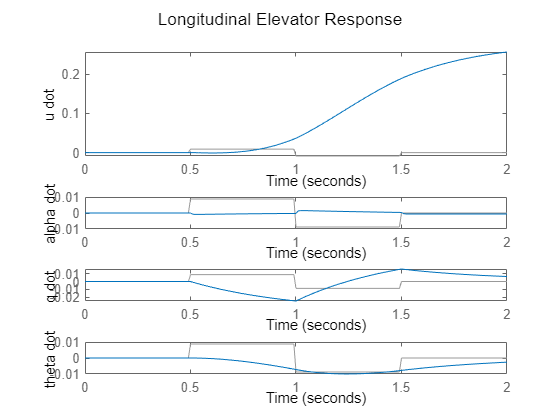

% Longitudinal Elevator Response
t = 0:.01:2;
u = zeros(size(t));
u(51:100) = .5*pi/180;
u(101:150) = -.5*pi/180;

figure;
sgtitle('Longitudinal Elevator Response')
subplot(5,1,[1 2]);
lsim(udotde, u, t);
ylabel('u dot');
title(' ');

subplot(5,1,3);
lsim(alphadotde, u, t);
ylabel('alpha dot');
title(' ');

subplot(5,1,4);
lsim(qdotde, u, t);
ylabel('q dot');
title(' ');

subplot(5,1,5);
lsim(thetadotde, u, t);
ylabel('theta dot');
title(' ');

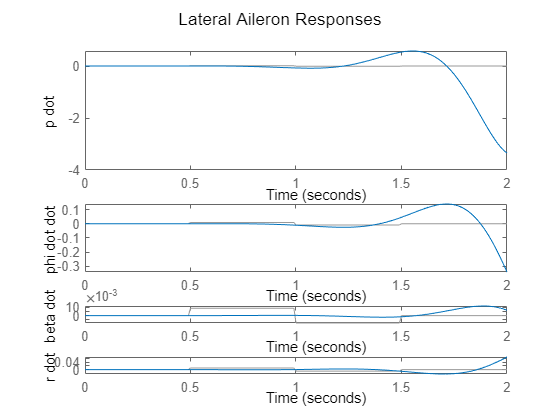


% Lateral Aileron Response
figure;
subplot(7,1,[1 2 3]);
sgtitle('Lateral Aileron Responses');
lsim(pdotda, u, t);
ylabel('p dot');
title(' ');

subplot(7,1,[4 5]);
lsim(phidotda, u, t);
ylabel('phi dot dot');
title(' ');

subplot(7,1,6);
lsim(betadotda, u, t);
ylabel('beta dot');
title(' ');

subplot(7,1,7);
lsim(rdotda, u, t);
ylabel('r dot');
title(' ');

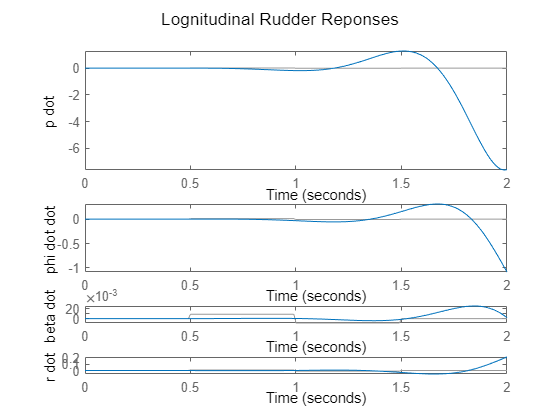


%Lateral Rudder Response
figure;
subplot(7,1,[1 2 3]);
sgtitle('Lognitudinal Rudder Reponses');
lsim(pdotdr, u, t);
ylabel('p dot');
title(' ');

subplot(7,1,[4 5]);
lsim(phidotdr, u, t);
ylabel('phi dot dot');
title(' ');

subplot(7,1,6);
lsim(betadotdr, u, t);
ylabel('beta dot');
title(' ');

subplot(7,1,7);
lsim(rdotdr, u, t);
ylabel('r dot');
title(' ');